# Расчёт полосно-заграждающего фильтра

Данный скрипт использует **MATLAB** и **Signal Processing Toolbox**

### Импорт аудио

Загрузим входной аудио-файл, который мы будем пропускать через фильтр, и послушаем его:

[x,fs] = audioread('energy.mp3');
% sound(x,fs);

### Зададим объект спецификации фильтра

Мы хотим рассчитать полосно-заграждающий фильтр со следующей спецификацией:

Полоса пропускания - от 0 до 500 Гц

Полоса заграждения - от 1000 до 4000 Гц

Полоса пропускания - от 4500 Гц до 22050 Гц

Пульсации в полосах пропускания - не более 1 дБ

Подавление в полосе заграждения - не менее 40 дБ

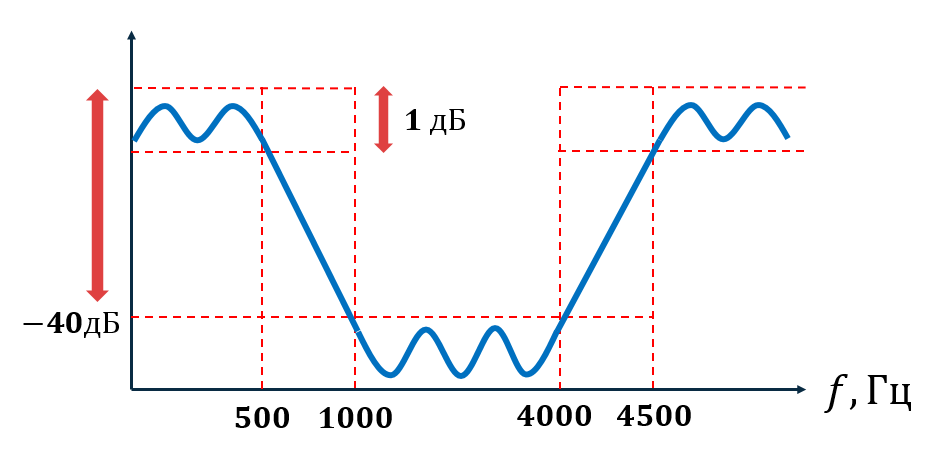

Объект спецификации формируется при помощи команды **fdesign**. В нашем случае мы сразу указываем тип специфкации **banstop**, и задаём набор численных значений параметров:

d = fdesign.bandstop('Fp1,Fst1,Fst2,Fp2,Ap1,Ast,Ap2',500,1000,4000,4500,1,40,1,fs)

d =   bandstop with properties:

               Response: 'Bandstop'
          Specification: 'Fp1,Fst1,Fst2,Fp2,Ap1,Ast,Ap2'
            Description: {7×1 cell}
    NormalizedFrequency: 0
                     Fs: 44100
                 Fpass1: 500
                 Fstop1: 1000
                 Fstop2: 4000
                 Fpass2: 4500
                 Apass1: 1
                  Astop: 40
                 Apass2: 1


### Посчёт коэффициентов фильтра

Оценим доступные методы реализации фильтра:

methods_iir = designmethods(d,'iir')

methods_iir = 4×1 cell array
    {'butter'}
    {'cheby1'}
    {'cheby2'}
    {'ellip' }


methods_fir = designmethods(d,'fir')

methods_fir = 2×1 cell array
    {'equiripple'}
    {'kaiserwin' }


Для вычисления коэффицентов фильтра мы используем функцию **design**, которой мы передаём объект спецификации фильтра и тип фильтра. В нашем случае это КИХ-фильтр типа **equiripple**. Оценим характеристики фильтра и их соответствие спецификации в программе **FVTOOL**: 

Hd = design(d,'equiripple')

Hd =      FilterStructure: 'Direct-Form FIR'                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                            

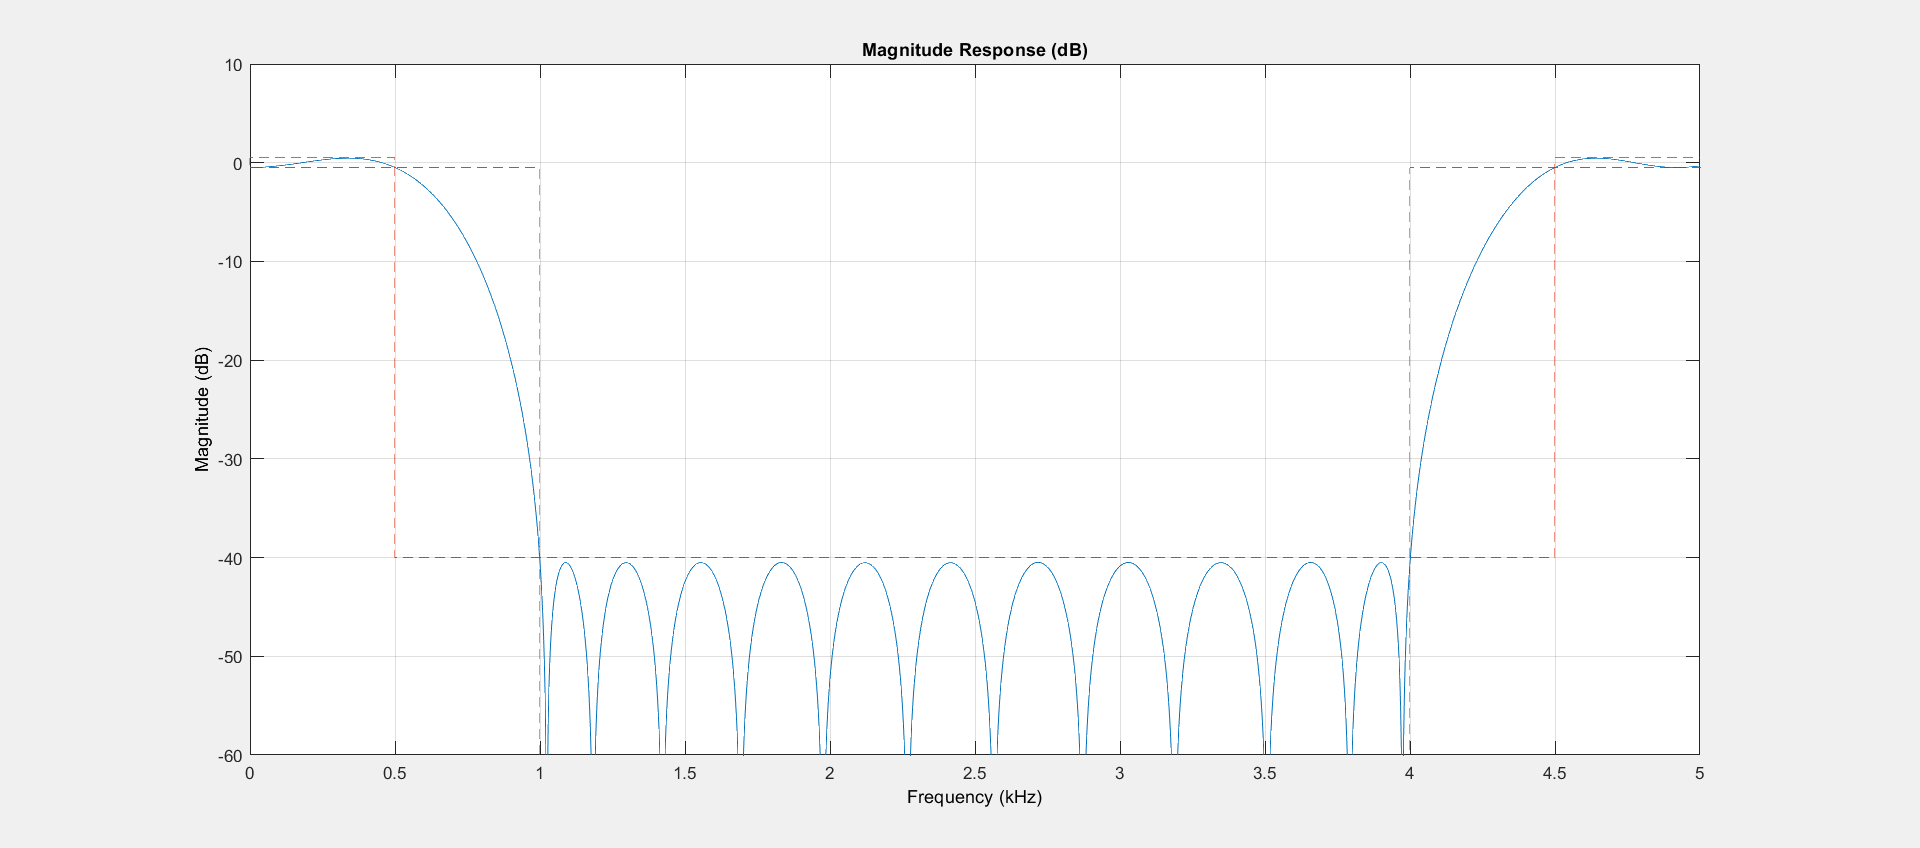

fvt1 = fvtool(Hd);
axis([0,5,-60,10]);

Отобразим коэффциенты числтеля передаточной функции фильтра на графике:

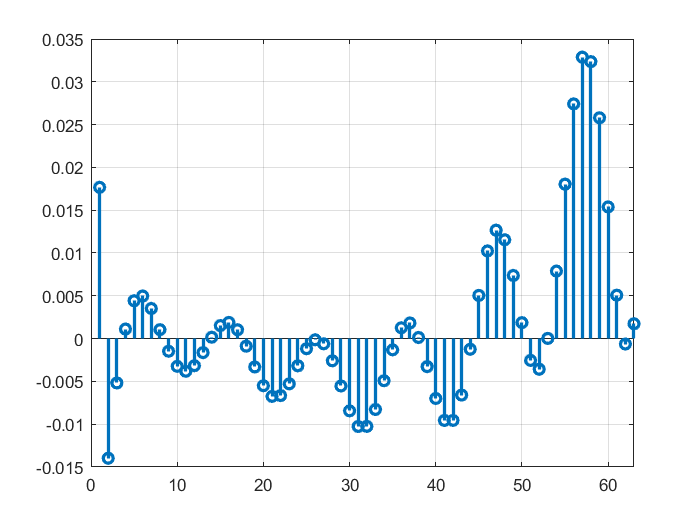

stem(Hd.Numerator,'LineWidth',2);
grid on;
xlim([0 63]);

### Применение фильтра

Отфильтруем входной сигнал командой **filter** и прослушаем результат:

y = filter(Hd,x);
% sound(y,fs);

### Сравнение спектов входного и выходного сигналов

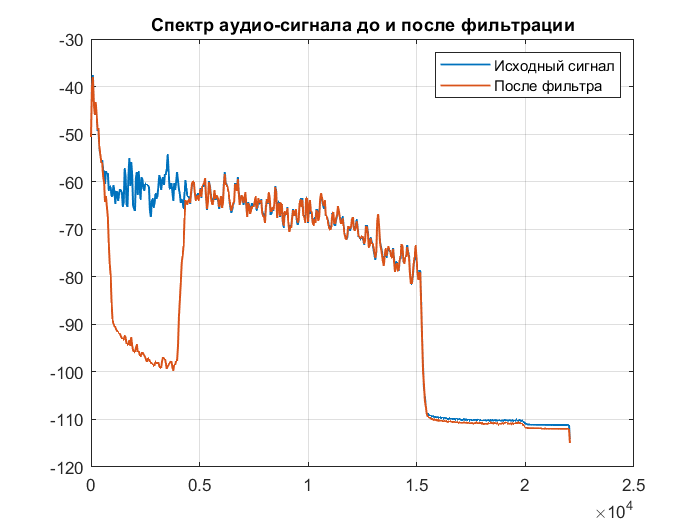

[pxx,ff] = pwelch(x,1024,512,1024,fs);
pyy = pwelch(y,1024,512,1024,fs);
plot(ff,10*log10(pxx),'LineWidth',1)
grid
hold on
plot(ff,10*log10(pyy),'LineWidth',1)
hold off
title('Спектр аудио-сигнала до и после фильтрации')
legend('Исходный сигнал','После фильтра')